th = 'C:\Users\Skill\MATLAB\TransManga\TransManga\Pictures';
[folder, baseFileNameNoExt, extension] = fileparts(th);


dbCtrl = DBCtrl();
[imgPathReadList, imgPathWriteList] = dbCtrl.getFileNamesList();

numImg = length(imgPathReadList);
for i=1:numImg
    I = imread2gray(imgPathReadList{i});    
    I_Bubbles = detectBubbles(I);
    
    [subFolderPathR, basePathR, extensionR] = fileparts(imgPathReadList{i});
    [subFolderPathW, basePathW, extensionW] = fileparts(imgPathWriteList{i});
    
    [status, msg] = mkdir(subFolderPathW);
    
    imwrite(I, fullfile(subFolderPathW, strcat(basePathR,extensionR) ) );
    imwrite(I_Bubbles, imgPathWriteList{i});
end

imshow(I_Bubbles);

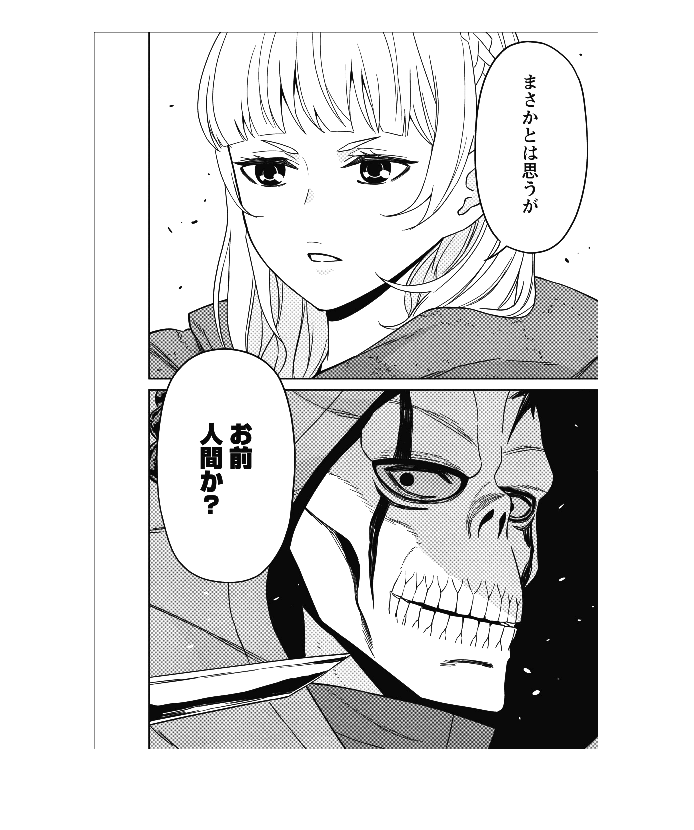

[I, map] = imread(imgPathReadList{154}, "BackgroundColor", 1);
gray = ind2gray(I, map);
imshow(gray);

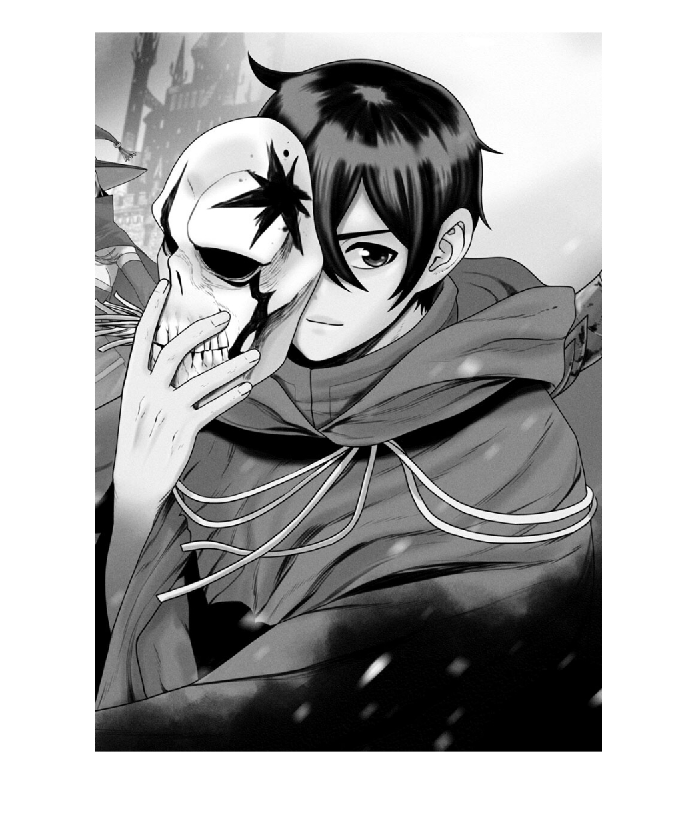

name = '07 (7).jpg';
gray = imread2gray(name);

imshow(gray);